folder = "DB0"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  %imshow(Im{i}) %%Show the current image in a subplot.
end

Convert to YCbCr and create an eye map according to the *Face Detection in Color Images* paper.

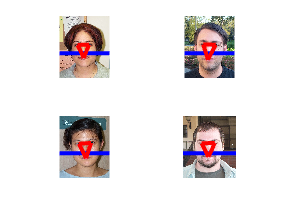

%The following requires image processing toolbox.

figure;
for i = 1:length(Im)
    
    subplot(length(Im)/2, length(Im)/2, i); %%define location to plot the image in our subplot.
    currentImage = Im{i};
EyeMap = eye_detection(currentImage);
size_img = size(currentImage);

MouthMap = mouth_detection(currentImage);

[lEye, rEye, mouth] = face_triangle_coordinates(MouthMap, EyeMap);



imshow(currentImage)
hold on
plot([1,size_img(2)],[3/5*size_img(1),3/5*size_img(1)],'Color','b','LineWidth',2)
plot([lEye(1),rEye(1)],[lEye(2),rEye(2)],'Color','r','LineWidth',2)
plot([mouth(1),rEye(1)],[mouth(2),rEye(2)],'Color','r','LineWidth',2)
plot([mouth(1),lEye(1)],[mouth(2),lEye(2)],'Color','r','LineWidth',2)
hold off

end 